%L3.a. Proportional controller design, lag compensator design

% Problem 1
% Proportional controller (Gain adjustment) design using Bode plot
% Find the value of gain K to yield 9.5% overshoot

% Percent overshoot
OS=9.5;
% Open loop transfer function coefficients
numg=[100];
deng=poly([0 -36 -100]);
% Transfer function
G=tf(numg,deng);
% Required damping ratio
z=(-log(OS/100))/sqrt(pi^2+(log(OS/100))^2)
% Required phase margin
pmreq=atan((2*z)/(sqrt(-2*z^2+sqrt(1+4*z^4))))*(180/pi)
% Frequency range
w=logspace(-2,3,1000);
% Bode plot of uncompensated system
figure(1)
bode(G,w)
grid on
% Determine wgc and Mdb from the plot
% Phase = -180 + pmreq
% Read corresponding magnitude Mdb from graph
% Gain required
% K=10^((-Mdb)/20)
K = 39
%K=input('Enter the value of K obtained from Bode plot = ');
% Compensated transfer function
numgn=K*numg;
% Verify Bode plot
hold on
bode(tf(numgn,deng),w)
% Closed loop transfer function
T=feedback(K*G,1);
% Step response
figure(2)
step(T)
grid on
title('Closed Loop Step Response')
% Compensated open loop transfer function
CGC=K*G

%L3.a. Proportional controller design, lag compensator design

% Exercise 1
% Using Root Locus
% For the system
% G(s)=K(s+1.5)/(s(s+1)(s+10))
% Design the value of gain K to yield 1.52% overshoot
% Also estimate settling time, peak time and steady state error

% Transfer function coefficients
num=[1 1.5];
den=poly([0 -1 -10]);
% Transfer function
G=tf(num,den);
% Root locus plot
figure(1)
rlocus(G)
grid on
title('Original Root Locus Plot')
% Percent overshoot
OS=1.52;
% Damping ratio
z=(-log(OS/100))/sqrt(pi^2+(log(OS/100))^2)
% Damping ratio line
sgrid(z,0)
title(['Root Locus Plot with ' num2str(OS) '% Overshoot Line'])
% Select desired closed loop pole
[K,P]=rlocfind(G)
% Closed loop transfer function
T=feedback(K*G,1);
% Step response
figure(2)
step(T)
grid on
% Settling time
TS=-4/real(P(1))
% Peak time
TP=pi/abs(imag(P(1)))
% Velocity error constant
s=tf([1 0],1);
KV=dcgain(s*G)
% Steady state error for ramp input
Ess=1/KV

%L3.a. Proportional controller design, lag compensator design

% Problem 2
% Lag compensator design using Bode plot
% Design specifications:
% Kv=5
% PM=40 deg
% GM>10 dB
% G(s)=1/(s(s+1)(0.5s+1))

% Design specifications
KV=5;
PM=40;
GM=10;
% Uncompensated system
numg=[1];
deng=conv(conv([1 0],[1 1]),[0.5 1]);
% Transfer function
G=tf(numg,deng);
% Gain required to satisfy Kv
K=KV/dcgain(tf(conv([1 0],numg),deng))

K = 5

% Frequency range
w=logspace(-1,2,100);
% Gain and phase data
[mag,ang]=bode(K*numg,deng,w);
% Gain margin and phase margin
[gm,pm,wcg,wcp]=margin(mag,ang,w)

gm = 0.6000

pm = -12.9790

wcg = 1.4142

wcp = 1.8018

% Obtain Bode plot
figure(1)
margin(K*G)
grid on
% Determine omega_m from phase plot
% Phase = -180 + PM + allowance
% Allowance typically 8 to 12 degrees
% Measure gain M dB at omega_m from magnitude plot
% Compute beta
% beta=10^(M/20)
beta=input('Enter value of beta = ');
% Upper corner frequency
wh=input('Enter omega_h = omega_m/10 : ');
% Lower corner frequency
wl=wh/beta;
% Lag compensator gain
kc=wl/wh;
% Lag compensator transfer function
lagc=tf(kc*[1 wh],[1 wl]);
% Compensated system
CGCS=K*G*lagc;
% Verify steady state error constant
S=tf([1 0],1);
KVF=dcgain(S*CGCS)
% Closed loop system
CLS=feedback(CGCS,1);
% Gain margin and phase margin
figure(2)
margin(CGCS)
grid on
% Step response
figure(3)
step(CLS)
grid on

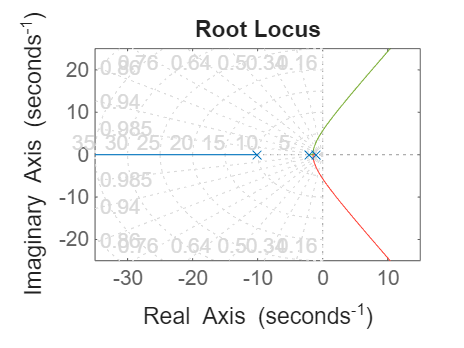

%L3.a. Proportional controller design, lag compensator design

% Problem 3
% Design a lag compensator to improve steady state error
% by a factor of 10 while maintaining damping ratio 0.174
% G(s)=1/((s+1)(s+2)(s+10))

% Transfer function variable
s=tf('s');
% Uncompensated system
g1=1/((s+1)*(s+2)*(s+10));
% Root locus
figure(1)
rlocus(g1)
grid on
% Desired damping ratio
z=0.174;
% Damping ratio line
sgrid(z,0)

% Select operating point
[k,p]=rlocfind(g1)
% Position error coefficient
kp=dcgain(k*g1)
% Steady state error
ess=1/(1+kp)
% Desired position error coefficient
kp1=9+10*kp;
% Beta of lag network
beta=(kp1/kp)*1.1
% Zero of lag network
zlag=0.1;
% Pole of lag network
plag=zlag/beta;
% Lag compensator
gclag=(s+zlag)/(s+plag);
% Compensated open loop transfer function
cgc=g1*gclag;
% Transfer function in zero-pole-gain form
zpk(cgc)
% Root locus of compensated system
figure(2)
rlocus(cgc)
grid on
% Desired damping ratio line
sgrid(z,0)
% Select compensated operating point
[k1,p]=rlocfind(cgc)
% Position error coefficient after compensation
kpf=dcgain(k1*cgc)
% Steady state error after compensation
ess1=1/(1+kpf)
% Improvement factor
ess/ess1
% Uncompensated closed loop response
cltfu=feedback(k*g1,1);
figure(3)
step(cltfu)
hold on
% Compensated closed loop response
cltfc=feedback(k1*cgc,1);
step(cltfc)
grid on
legend('Uncompensated','Compensated')

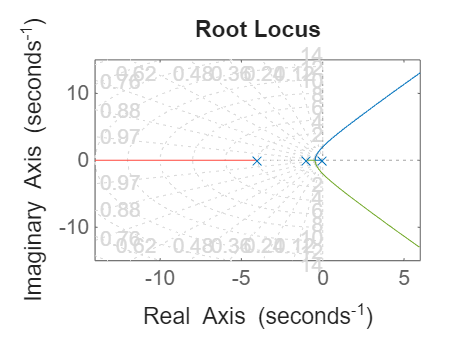

%L3.a. Proportional controller design, lag compensator design

% Exercise 2
% Lag compensator design using Root Locus
% Desired specifications:
% zeta=0.5
% Ts=10 s
% Kvf=5

s=tf('s');
% Type 1 system
g1=1/(s*(s+1)*(s+4));
% Root locus
figure(1)
rlocus(g1)
grid on

% Specifications
z=0.5;
TS=10;
kvf=5;
% Natural frequency
wn=4/(z*TS);
% Desired dominant pole
s1=-z*wn+1i*wn*sqrt(1-z^2)

s1 = -0.4000 + 0.6928i

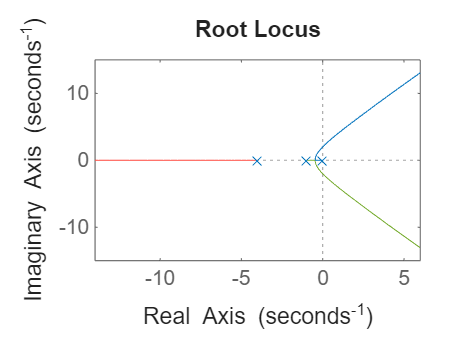

k = 2.6880

p =   -4.2000 + 0.0000i
  -0.4000 + 0.6928i
  -0.4000 - 0.6928i


% Gain for desired pole location
[k,p]=rlocfind(g1,s1)

% Velocity error constant
d1=s;
kv=dcgain(d1*k*g1)

kv = 0.6720

% Steady state error
ess=1/kv

ess = 1.4881

% Gain required to satisfy Kv specification
kgain=kvf/kv

kgain = 7.4405

% Lag network attenuation factor
beta=kgain*1.1

beta = 8.1845

% Lag compensator zero
zlag=0.2;
% Lag compensator pole
plag=zlag/beta;
% Lag compensator
gclag=(s+zlag)/(s+plag);
% Compensated open loop transfer function
cgc=g1*gclag;
% Zero-pole-gain form
zpk(cgc)


ans =
 
           (s+0.2)
  -------------------------
  s (s+4) (s+1) (s+0.02444)
 
Continuous-time zero/pole/gain model.
Model Properties


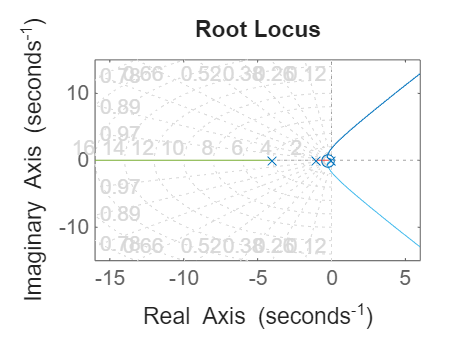

% Root locus of compensated system
figure(2)
rlocus(cgc)
grid on

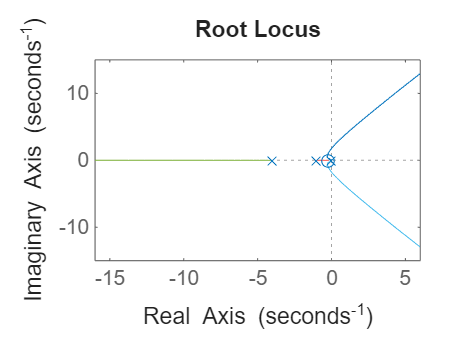

k1 = 2.9376

p1 =   -4.2084 + 0.0000i
  -0.2798 + 0.6829i
  -0.2798 - 0.6829i
  -0.2563 + 0.0000i


% Select compensated pole location
[k1,p1]=rlocfind(cgc,s1)

% Final velocity error constant
kvfinal=dcgain(d1*k1*cgc)

kvfinal = 6.0107

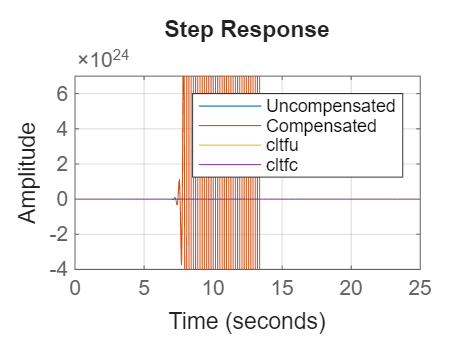

% Uncompensated closed loop system
cltfu=feedback(k*g1,1);
figure(3)
step(cltfu)
hold on
% Compensated closed loop system
cltfc=feedback(k1*cgc,1);
step(cltfc)
grid on
legend('Uncompensated','Compensated')

%L3.a. Proportional controller design, lag compensator design

% Exercise 3
% Design a lag compensator to improve the steady state error
% while maintaining zeta=0.174 and Ts=1 s
% G(s)=1/((s+1)(s+2)(s+10))

s=tf('s');
% Uncompensated system
g1=1/((s+1)*(s+2)*(s+10));
% Root locus
figure(1)
rlocus(g1)
grid on
% Design specifications
z=0.174;
TS=1;
% Desired natural frequency
wn=4/(z*TS);
% Desired dominant pole
s1=-z*wn+1i*wn*sqrt(1-z^2)

s1 = -4.0000 +22.6378i

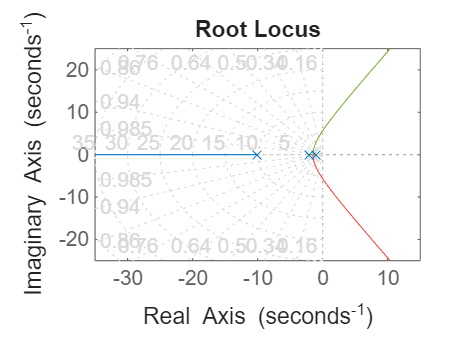

% Mark damping ratio line
sgrid(z,0)

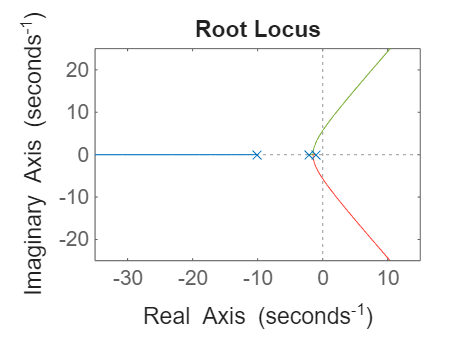

k = 1.2154e+04

p =  -27.7052 + 0.0000i
   7.3526 +19.6303i
   7.3526 -19.6303i


% Select gain at desired pole location
[k,p]=rlocfind(g1,s1)

% Position error coefficient
kp=dcgain(k*g1)

kp = 607.6946

% Steady state error
ess=1/(1+kp)

ess = 0.0016

% Improve steady state error by a factor of 10
kp1=9+10*kp;
% Lag network attenuation factor
beta=(kp1/kp)*1.1

beta = 11.0163

% Lag compensator zero
zlag=0.1;
% Lag compensator pole
plag=zlag/beta;
% Lag compensator transfer function
gclag=(s+zlag)/(s+plag);
% Compensated open loop transfer function
cgc=g1*gclag;
% Transfer function in zero-pole-gain form
zpk(cgc)


ans =
 
              (s+0.1)
  -------------------------------
  (s+10) (s+2) (s+1) (s+0.009077)
 
Continuous-time zero/pole/gain model.
Model Properties


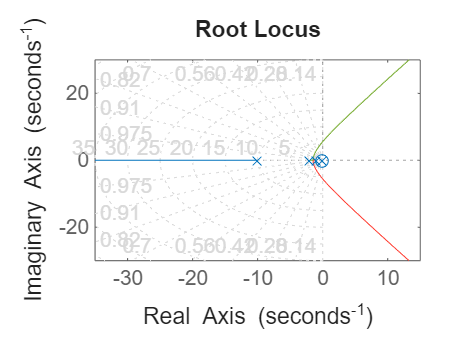

% Root locus of compensated system
figure(2)
rlocus(cgc)
grid on
% Mark damping ratio line
sgrid(z,0)

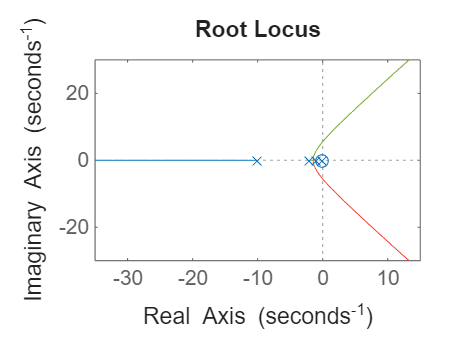

k1 = 1.2162e+04

p1 =  -27.6855 + 0.0000i
   7.3882 +19.6299i
   7.3882 -19.6299i
  -0.0999 + 0.0000i


% Select compensated gain
[k1,p1]=rlocfind(cgc,s1)

% New position error coefficient
kpf=dcgain(k1*cgc)

kpf = 6.6991e+03

% New steady state error
ess1=1/(1+kpf)

ess1 = 1.4925e-04

% Improvement factor
ess/ess1

ans = 11.0073

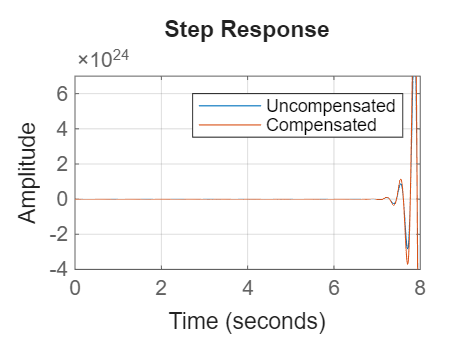

% Uncompensated closed loop response
cltfu=feedback(k*g1,1);
figure(3)
step(cltfu)
hold on
% Compensated closed loop response
cltfc=feedback(k1*cgc,1);
step(cltfc)
grid on
legend('Uncompensated','Compensated')